# Figure 3 - Grouping data from 405/415 but not 450 excitation lights

We compare the different excitation lights, justifying how we grouped the 405/415 but not the 450 nm excitation light.

To measure lip and tongue fluorescence we needed to remove any reflected light from the light source.  These were always below 475nm, so added a 475 nm long pass to the system.  This blocked the reflected light, but allowed fluorescent light to pass. For more explanation, see Figure 1.

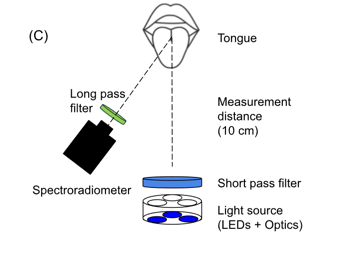

## Initialize ISET

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};
fise_plotDefaults;

% Not normalized.
nWave = 520;  % 580 
yScale = 'linear';
T = oeDatabaseCreate;

## Lip fluorescence with three different excitation lights (Figure 3A)

### 405 (980 mA)

lipFiles405 = ieTableGet(T,'ewave',405,'substrate','lip','elevel',980,'return','files');
data = oeReadFiles(lipFiles405,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(lipFiles405)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hA = plot(waves,data(:,ii),'b-'); hold on;
    set(hA,'LineWidth',2);
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')

% If no nWave, we did not normalize
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized Radiance (re: %d nm)',nWave));
end

### 415 (910 mA)

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910);

% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = oeReadFiles(lipFiles415,'waves',waves,'normalized wave',nWave);

% ieFigure;
for ii= 1:numel(lipFiles415)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hB = plot(waves,data(:,ii),'g-'); hold on; 
    set(hB,'LineWidth',2);
    set(gca,'yscale',yScale);
end

### 450 (870 mA)

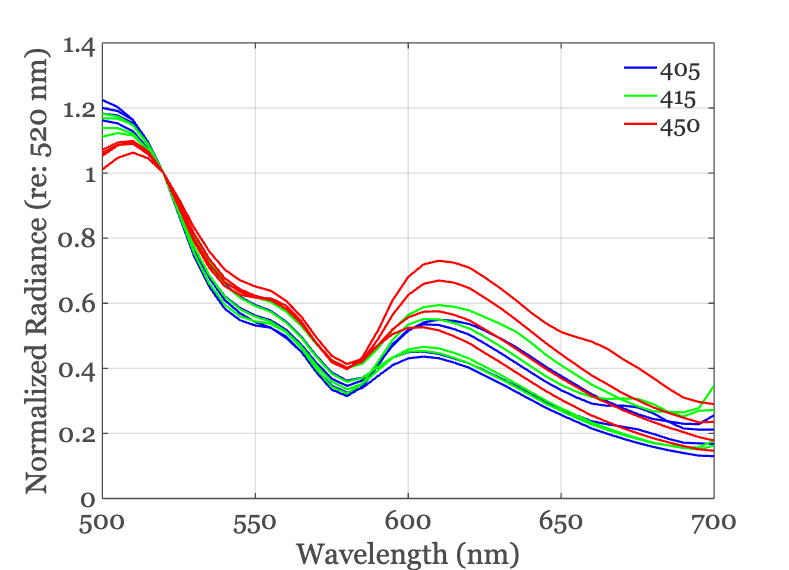

lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');

data = oeReadFiles(lipFiles450,'waves',waves,'normalized wave',nWave);

% ieFigure;
hold on;
for ii= 1:numel(lipFiles450)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hC = plot(waves,data(:,ii),'r-'); hold on; 
    set(hC,'LineWidth',2);
    set(gca,'yscale',yScale);
end
legend([hA,hB,hC],{'405','415','450'});
set(gca,'Fontsize',24);
fname = fullfile(oeTongueLipRootPath,'figures','Figure3A.svg');
print(gcf,fname,'-dsvg');

%exportgraphics(gcf,'figure3A.png','Resolution',150);

## Tongue excitations (Figure 3B)

### 405 (980 mA)

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');
data = oeReadFiles(tongueFiles405,'waves',waves,'normalized wave',nWave);
selected = [1 3 4 5];
tongueFiles405 = tongueFiles405(selected);

ieFigure;
for ii= 1:numel(tongueFiles405)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hA = plot(waves,data(:,ii),'b-'); hold on;
    set(hA,'LineWidth',2);
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')

% If no nWave, we did not normalize
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized radiance (re: %d nm)',nWave));
end

% title('Lip (405 ex)');
% legend({'J','Z','B','D'});

### 415 (910 mA)

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910);

% Collected on the same day as above.
selected = [1 3 5 7];
tongueFiles415 = tongueFiles415(selected);

data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);

% ieFigure;
for ii= 1:numel(tongueFiles415)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hB = plot(waves,data(:,ii),'g-'); hold on; 
    set(hB,'LineWidth',2);
    set(gca,'yscale',yScale);
end

### 450 (870 mA)

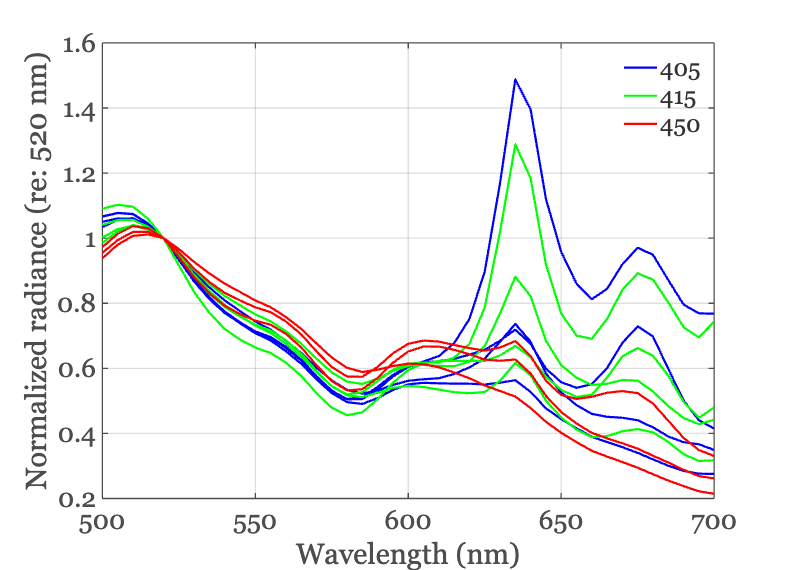

tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');

data = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

hold on;
for ii= 1:numel(tongueFiles450)
    hC = plot(waves,data(:,ii),'r-'); hold on; 
    set(gca,'yscale',yScale);
    set(hC,'LineWidth',2);
end
legend([hA,hB,hC],{'405','415','450'});
set(gca,'Fontsize',24);
fname = fullfile(oeTongueLipRootPath,'figures','Figure3B.svg');
print(gcf,fname,'-dsvg');

%exportgraphics(gcf,'figure3B.png','Resolution',150);